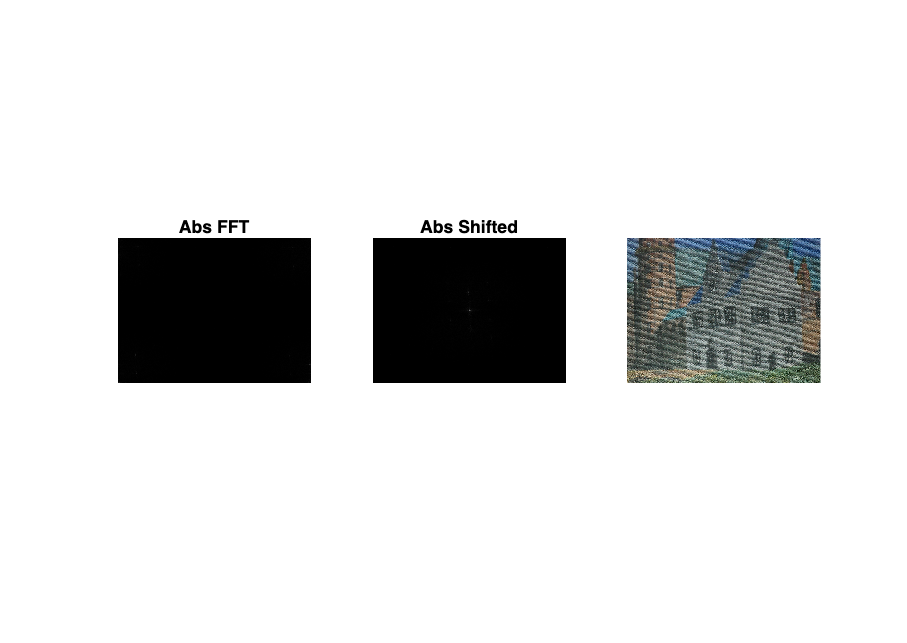

old = im2double(imread('185-8526_IMG.jpg'));
imshow(old);

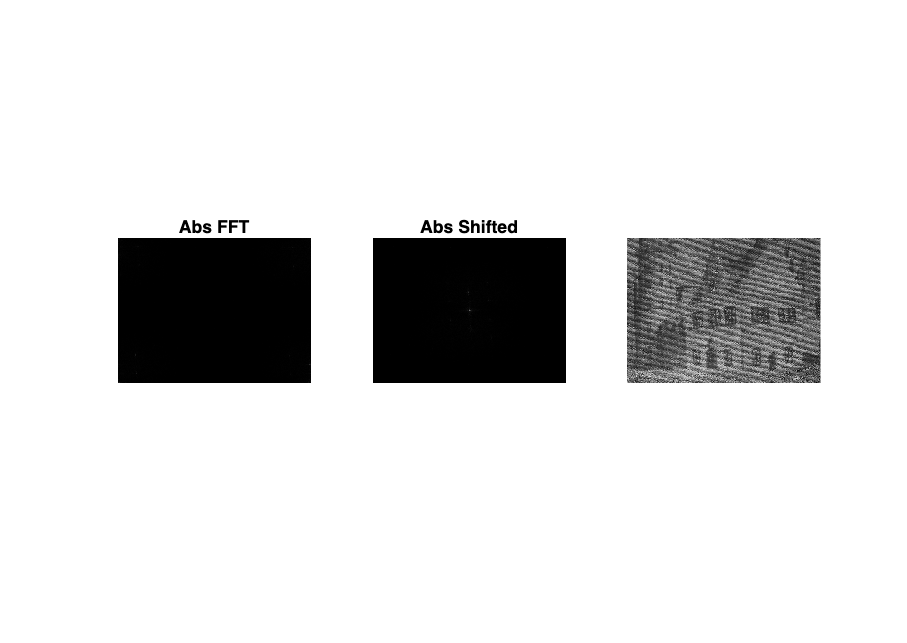

gray_old = rgb2gray(old);
imshow(gray_old);

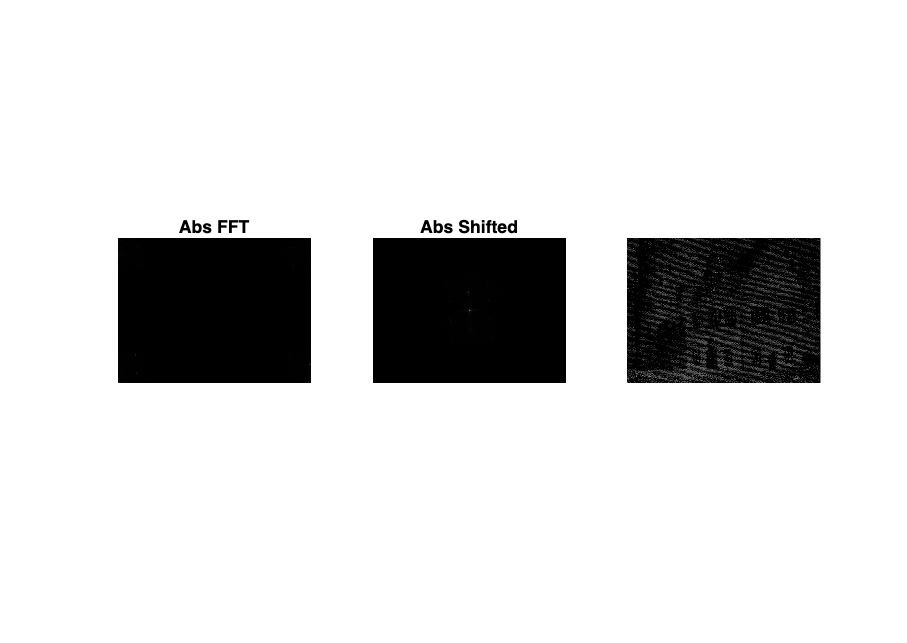

mean_grayscale = mean2(old);
new_image = gray_old - mean_grayscale;
imshow(new_image);

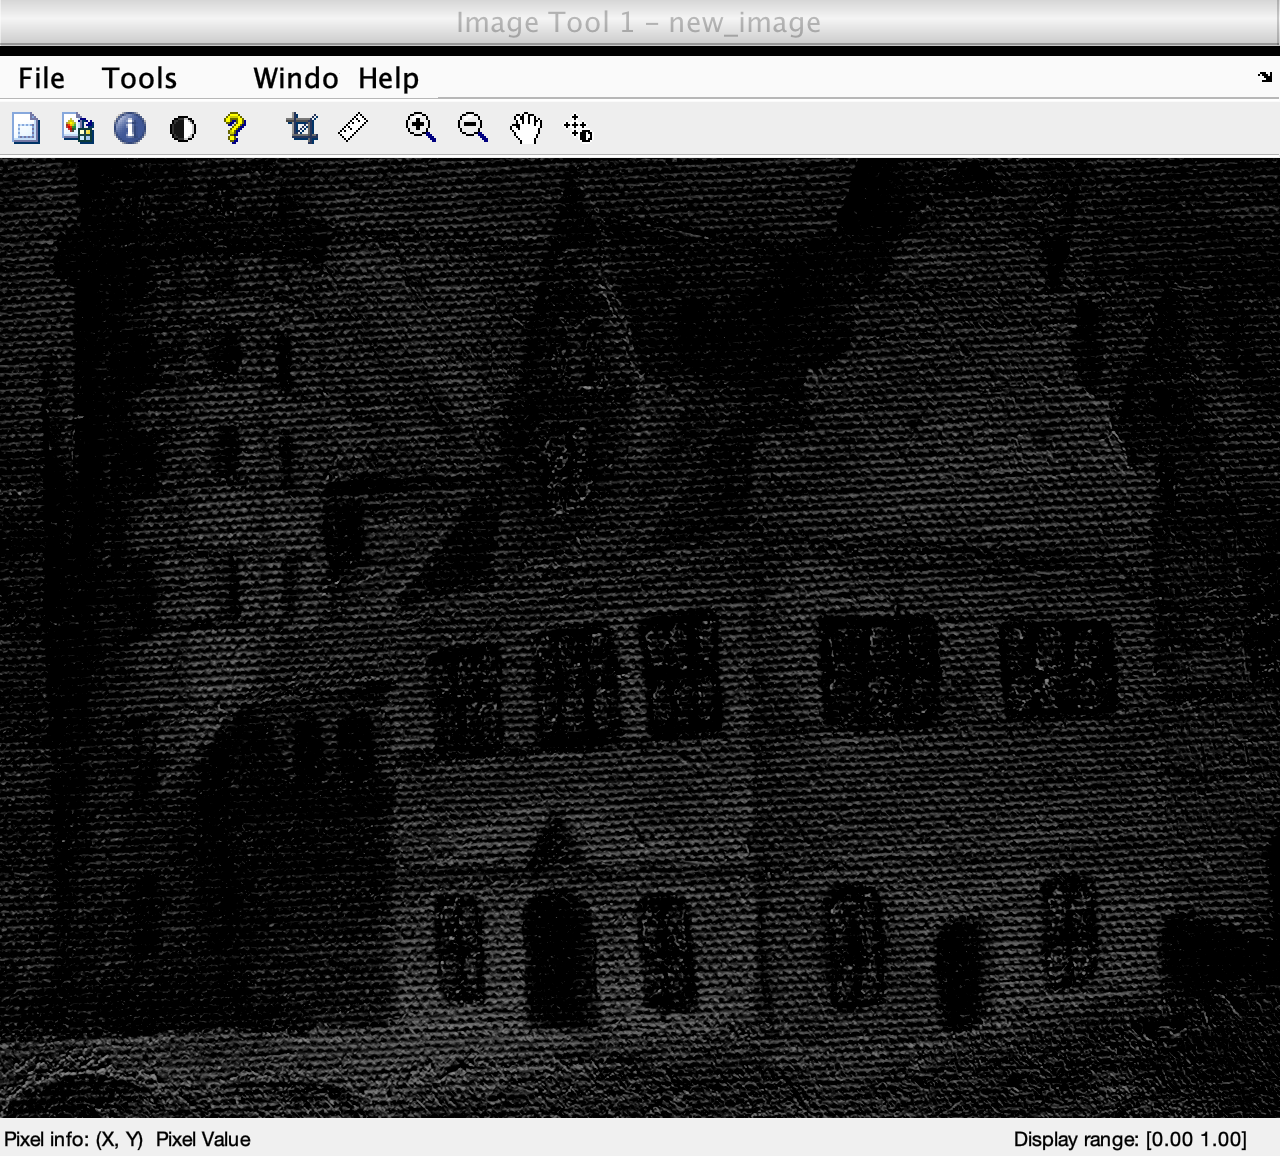

imtool(new_image)

fft = fft2(new_image);
abs_fft = abs(fft);
shifted_fft = fftshift(fft);
abs_shifted_fft = abs(shifted_fft);
log_shift_fft = rescale(log(abs_shifted_fft + 1), 0,256);

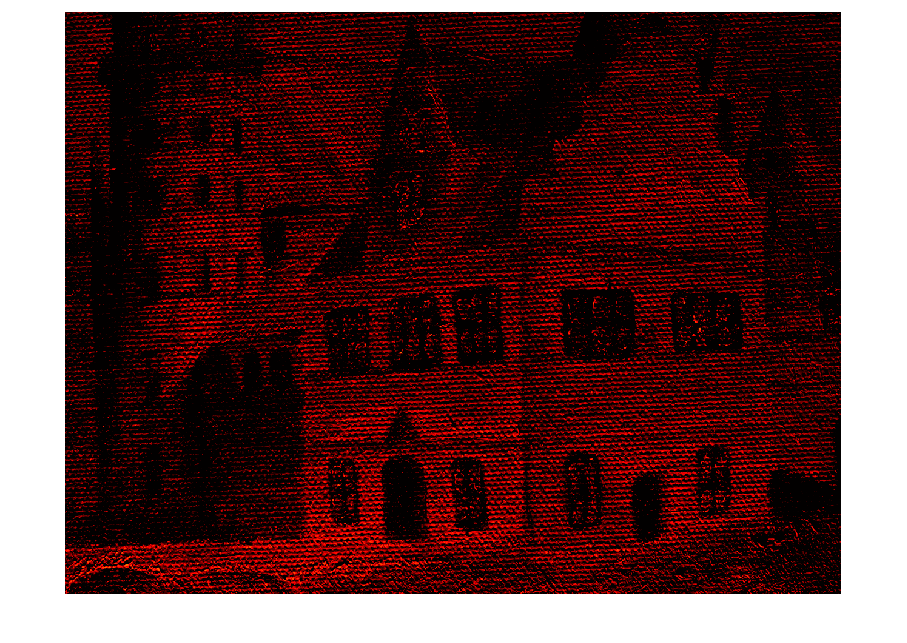


colormap hot;

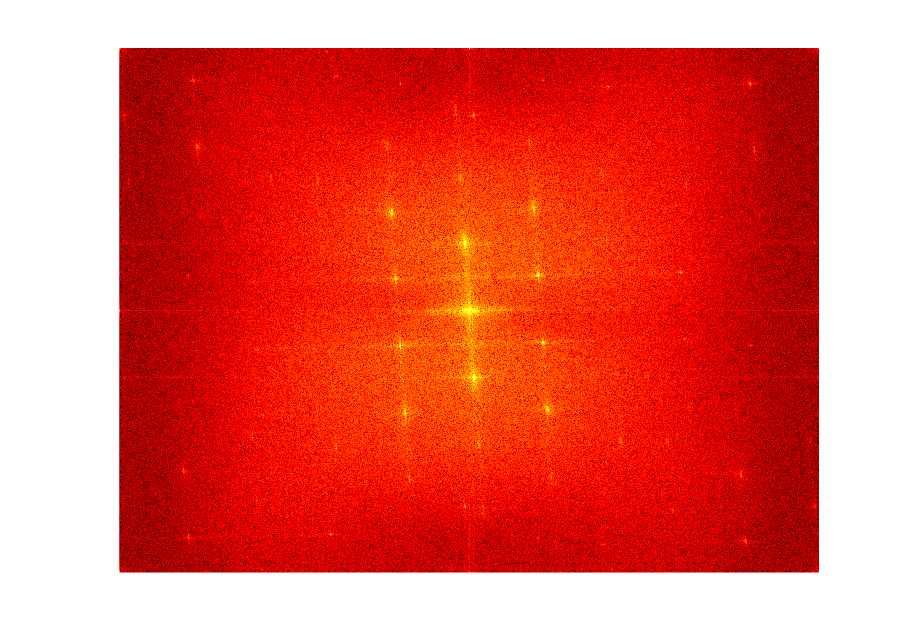

imagesc(log_shift_fft);
axis off;
axis image;

colormap hot;

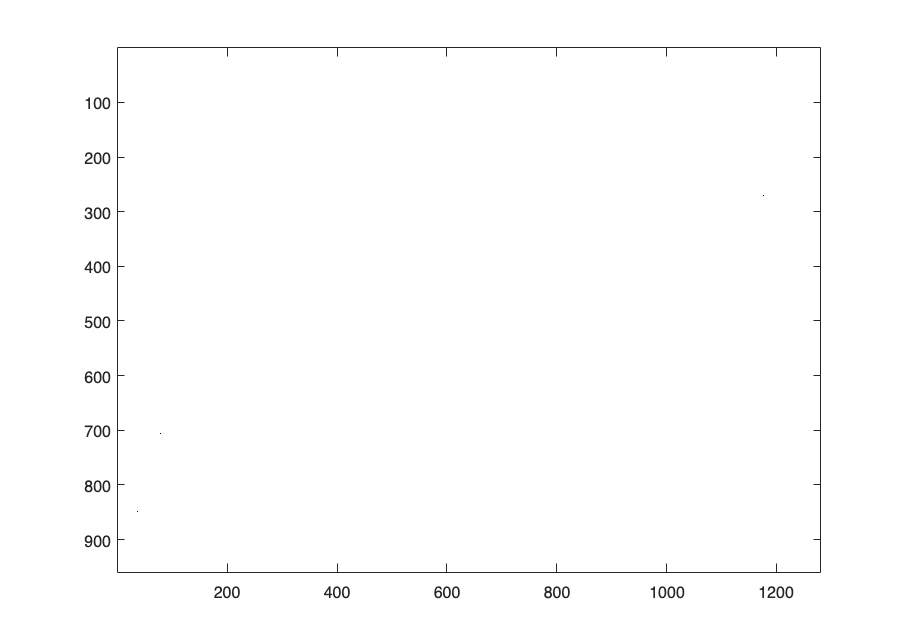

image_log = imbinarize(log_shift_fft);
imagesc(image_log);

%goal is to save the log_shift_fft image and mask it
size(log_shift_fft) %grayscale

ans =          960        1280


Rmax = max(log_shift_fft,[], 'all')

Rmax = 256

Rmin  = min(log_shift_fft,[], 'all')

Rmin = 0

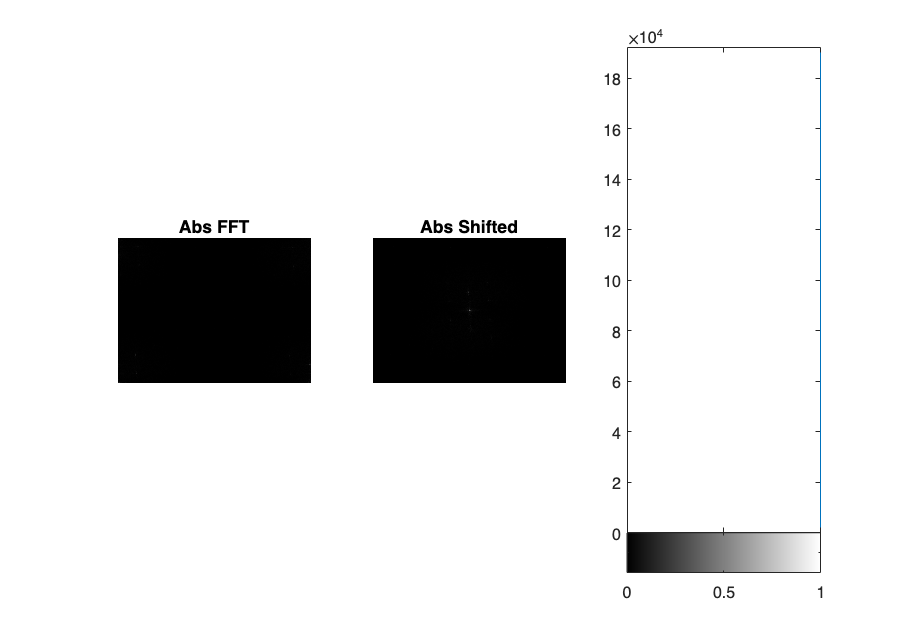

imhist(log_shift_fft)

mask = fft2(image_log); 
mask = fftshift(mask);
red = fft2(old(:,:,1)) .* mask ; 
blue = fft2(old(:,:,3)) .* mask;
green = fft2(old(:,:,2)) .* mask

green = 1.0e+08 *

   0.0196 + 0.0000i  -0.0006 + 0.0001i  -0.0003 + 0.0002i   0.0000 + 0.0000i  -0.0000 + 0.0001i  -0.0001 - 0.0003i  -0.0003 - 0.0000i  -0.0001 + 0.0003i  -0.0004 + 0.0001i   0.0000 + 0.0001i  -0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0001i  -0.0001 - 0.0005i  -0.0000 - 0.0000i   0.0000 - 0.0001i   0.0000 - 0.0002i  -0.0002 - 0.0001i  -0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0001i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0001i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0001i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0001i   0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0001i
  -0.0001 - 0.0003i  -0.0000 -

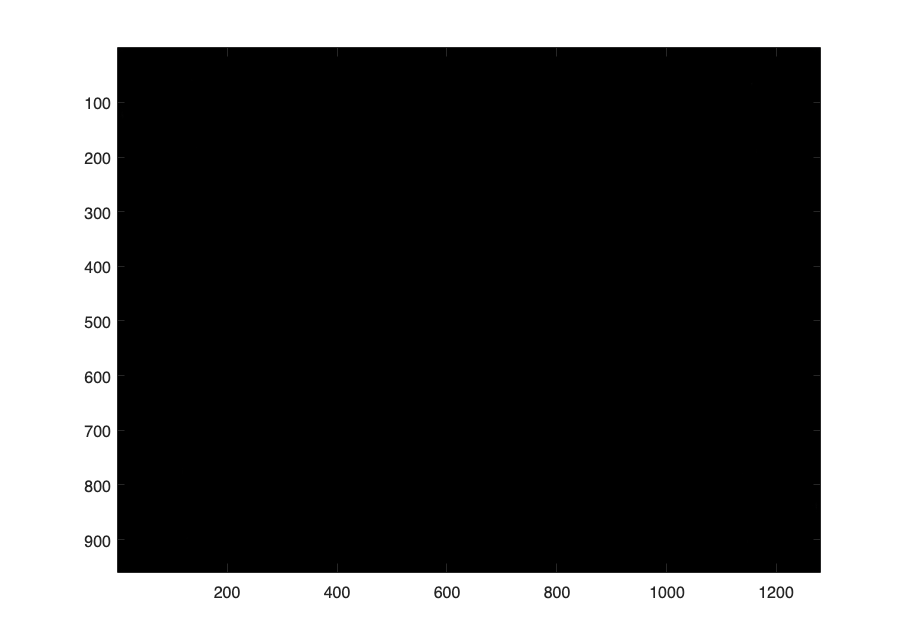


inv_mask = ifft2(old);
imagesc(abs(inv_mask));

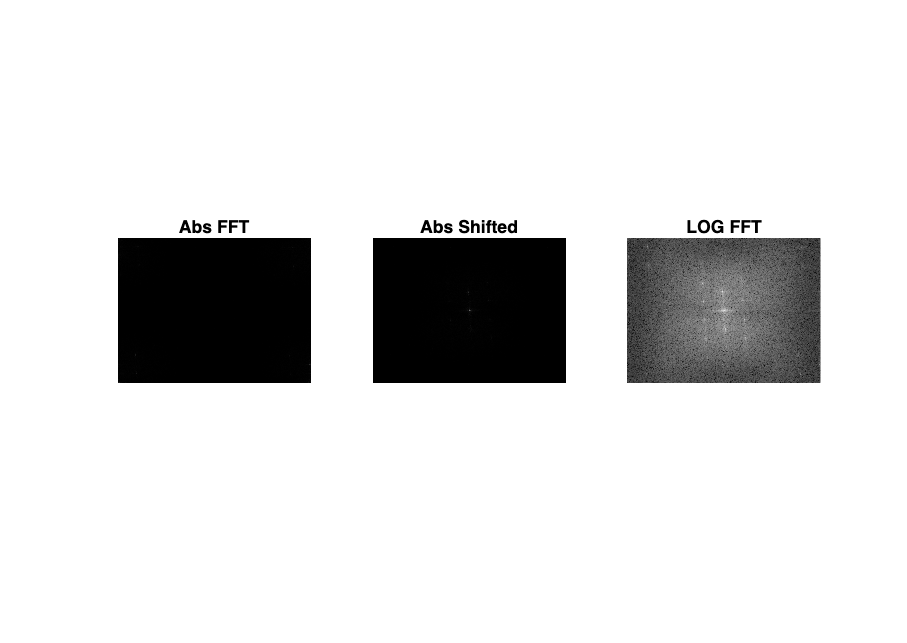

subplot(1,3,1);
imagesc(abs_fft);
axis off;
axis image;
title('Abs FFT');

subplot(1,3,2);
imagesc(abs_shifted_fft);
axis off;
axis image;
title('Abs Shifted');

subplot(1,3,3); 
imagesc(log_shift_fft)
axis off;
axis image; 
title('LOG FFT')
colormap gray;